bankData = readtable('BankMarketingForModelTraining.csv','PreserveVariableNames',true)

bankData = 5092×43 table
    default     housing      loan      duration     campaign     pdays     previous    poutcome     emp.var.rate    cons.conf.idx    euribor3m    nr.employed     admin.     blue-collar    entrepreneur    retired     services    student     unemployed    divorced    married     single     basic.4y    basic.6y    basic.9y    university.degree    unknown_education    cellular    telephone     Adult     Elderly      Young        <s

#### **Splitting the Data into training and testing**

cv = cvpartition(size(bankData,1),'HoldOut',0.3);
dataUpd = cv.test;
% Separate to training and test data
dataTrain = bankData(~dataUpd,:);

dataTest  = bankData(dataUpd,:);       

XTrain= dataTrain(1:end, 1:end-1)

XTrain = 3565×42 table
    default     housing      loan      duration    campaign     pdays     previous    poutcome     emp.var.rate    cons.conf.idx    euribor3m    nr.employed     admin.     blue-collar    entrepreneur    retired     services    student     unemployed    divorced    married     single     basic.4y    basic.6y    basic.9y    university.degree    unknown_education    cellular    telephone     Adult     Elderly      Young        

yTrain= dataTrain(1:end,end)

yTrain = 3565×1 table
    y
    _

    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0



XTest= dataTest(1:end, 1:end-1)

XTest = 1527×42 table
    default     housing      loan      duration     campaign     pdays     previous    poutcome     emp.var.rate    cons.conf.idx    euribor3m    nr.employed     admin.     blue-collar    entrepreneur    retired     services    student     unemployed    divorced    married     single     basic.4y    basic.6y    basic.9y    university.degree    unknown_education    cellular    telephone     Adult     Elderly      Young        

yTest= dataTest(1:end,end)

yTest = 1527×1 table
    y
    _

    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0
    0


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.18794 |    0.099124 |     0.18794 |     0.18794 |       normal |            - |
|    2 | Accept |     0.18794 |    0.080455 |     0.18794 |     0.18794 |       normal |            - |
|    3 | Accept |     0.19102 |       7.229 |     0.18794 |     0.18794 |       kernel |       10.374 |
|    4 | Best   |     0.13296 |      5.5024 |     0.13296 |     0.13296 |       kernel |    0.0075582 |
|    5 | Accept |     0.13885 |      5.6803 |     0.13296 |     0.13296 |       kernel |   0.00013426 |
|    6 | Best   |     0.12707 |      5.4724 |     0.12707 |     

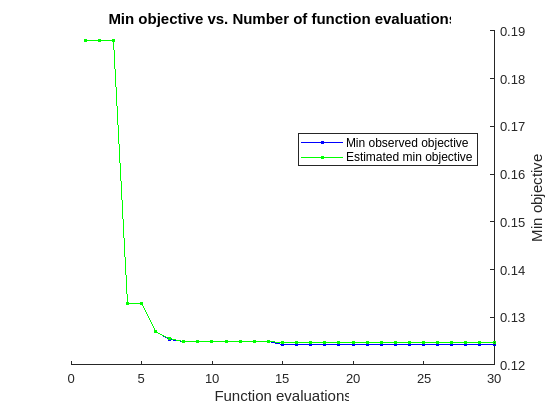

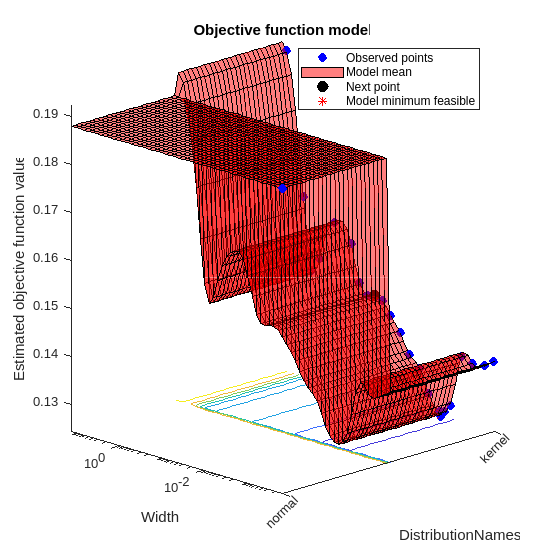


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 197.3801 seconds
Total objective function evaluation time: 166.5423

Best observed feasible point:
    DistributionNames      Width  
    _________________    _________

         kernel          0.0024612

Observed objective function value = 0.12426
Estimated objective function value = 0.12466
Function evaluation time = 5.5064

Best estimated feasible point (according to models):
    DistributionNames      Width  
    _________________    _________

         kernel          0.0024612

Estimated objective function value = 0.12466
Estimated function evaluation time = 5.5512



finalModelNB =   ClassificationNaiveBayes
                       PredictorNames: {1×42 cell}
                         ResponseName: 'y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 3565
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                    DistributionNames: {1×42 cell}
               DistributionParameters: {2×42 cell}
                               Kernel: {1×42 cell}
                              Support: {1×42 cell}
                                Width: [2×42 double]


  Properties, Methods


finalModelNB= fitcnb(XTrain,yTrain, 'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',struct('KFold',5))

#### Saving Model

save('finalModelNB.mat','finalModelNB', "yTest","XTest")